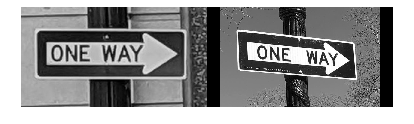

ow1 = imread("C:\Users\xxoox\OneDrive\デスクトップ\MATLAB works\Computer Vision for Engineering and Science\C1-IntroductionToComputerVision\Module 2\oneway1.png"); 
ow1 = im2gray(ow1);
ow2 = imread("C:\Users\xxoox\OneDrive\デスクトップ\MATLAB works\Computer Vision for Engineering and Science\C1-IntroductionToComputerVision\Module 2\oneway2.png"); 
ow2 = im2gray(ow2);
montage({ow1,ow2})

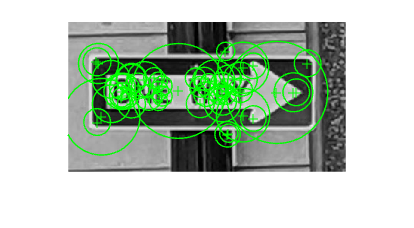


points1 = detectSURFFeatures(ow1);
points2 = detectSURFFeatures(ow2);

nKeep = 50; 
points1 = selectStrongest(points1,nKeep);
points2 = selectStrongest(points2,nKeep);

imshow(ow1)
hold on 
plot(points1)
hold off 

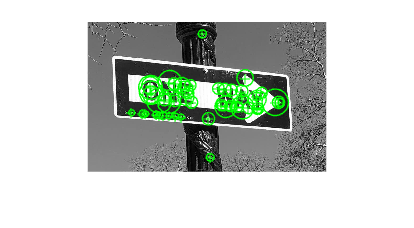



imshow(ow2)
hold on
plot(points2)
hold off


clf

[features1,validPoints1] = extractFeatures(ow1,points1);
[features2,validPoints2] = extractFeatures(ow2,points2);

indexPairs = matchFeatures(features1,features2)

indexPairs = 6×2 uint32 matrix
    8    3
    9   40
   10   20
   25   43
   29   36
   42    5


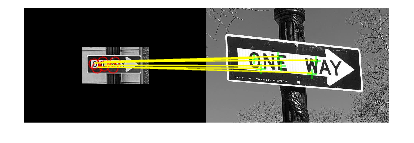


matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2)); 

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage")


indexPairs = matchFeatures(features1,features2,"MatchThreshold",1)

indexPairs = 6×2 uint32 matrix
    8    3
    9   40
   10   20
   25   43
   29   36
   42    5



matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2)); 

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage")


indexPairs = matchFeatures(features1,features2,"MatchThreshold",2,...
                                                "MaxRatio",1)

indexPairs = 19×2 uint32 matrix
    8    3
    9   40
   10   20
   15   39
   16   47
   17   32
   19   39
   20   50
   25   43
   26   36


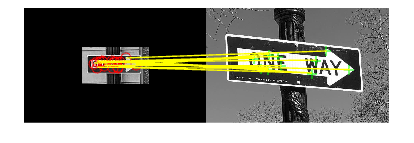


matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2)); 

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage")


nMatches = length(matchedPoints1); clf
idx = 11

idx = 11

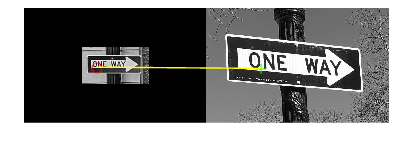


showMatchedFeatures(ow1,ow2,matchedPoints1(idx),matchedPoints2(idx),"montage")


indexPairs = matchFeatures(features1,features2,"MatchThreshold",2,...
                                                "MaxRatio",1,...
                                                "Unique",false)

indexPairs = 19×2 uint32 matrix
    8    3
    9   40
   10   20
   15   39
   16   47
   17   32
   19   39
   20   50
   25   43
   26   36




matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2)); 

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage");

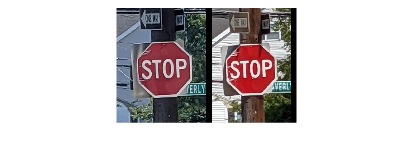



stop1RGB = imread("C:\Users\xxoox\OneDrive\デスクトップ\MATLAB works\Computer Vision for Engineering and Science\C1-IntroductionToComputerVision\Module 2\stop1.jpg");
stop2RGB = imread("C:\Users\xxoox\OneDrive\デスクトップ\MATLAB works\Computer Vision for Engineering and Science\C1-IntroductionToComputerVision\Module 2\stop2.jpg");
montage({stop1RGB,stop2RGB})

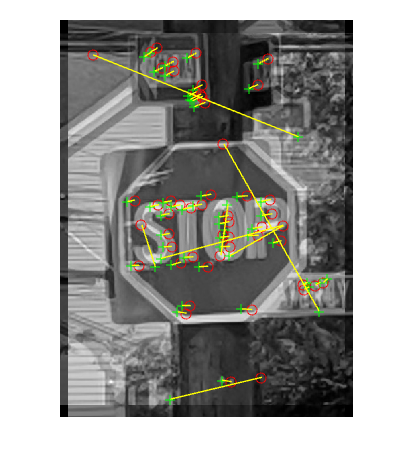



clf


stop1 = im2gray(stop1RGB);
stop2 = im2gray(stop2RGB);


pts1 = detectSURFFeatures(stop1);
pts2 = detectSURFFeatures(stop2);

[feat1,validPts1] = extractFeatures(stop1,pts1);
[feat2,validPts2] = extractFeatures(stop2,pts2);

indexPairs = matchFeatures(feat1,feat2,"MatchThreshold",48,...
                                        "MaxRatio",0.7,...
                                        "Metric",'SAD',...
                                        "Unique",true) ;

matchedPoints1 = validPts1(indexPairs(:,1));
matchedPoints2 = validPts2(indexPairs(:,2));


showMatchedFeatures(stop1,stop2,matchedPoints1,matchedPoints2,"blend")